Setup:

%% Balloon Radius Calculator for ASEN 2002 Lab Project 1
% By: Ian Faber, 09/07/21
clc; clear; close all;

syms m rho_air rho_gas rho_shell t_shell P_gage Y_S positive
syms r_balloon sigma F_S real

m_empty = 500; %500 kg payload
ballast = 100;

g = 9.8

g = 9.8000

m = m_empty + ballast

m = 600

P_gage = 10; %10 Pa
material = ["Lexan","Mylar","Consolidated GFI9X","Udel Slot Cast","High Density Polyethylene","Linear Low Density Polyethylene"];
%Densities converted from 0.0063, 0.0072, 0.0048, and 0.0043 lbf/ft^2 to
%kg/m^3 respectively. Polyethylene and LLDPE incorporated from Josh's
%research
rho_shell = [1211.1, 1384.1, 922.7, 826.6, 958, 917];
%Thicknesses converted from 1 mil (0.001 in) to m. Assumed 1 mil for
%Polyethylene and LLDPE
%t_shell = [2.54e-5, 2.54e-5, 2.54e-5, 2.54e-5, 2.54e-5, 2.54e-5];
%Yield strengths converted from 9820, 21920, 5470, and 4820 psi to Pa in the TRANSVERSE direction respectively
Y_S = [67710000, 151130000, 37710000, 33230000, 26800000, 10100000];
F_S = 4*ones([1 6]);
%Material properties source, page 30: https://opensky.ucar.edu/islandora/object/technotes%3A464/datastream/PDF

To find the density of helium, we need a modified ideal gas law:

%Ideal gas law: P = nkT, n = number density = rho_gas / m_gas_1_molecule, 
%k= boltzman's constant, P = pressure, T = temperature
k = 1.38e-23; % P = pressure, T = temperature
atomic_weight = 1.001; %g/mol, Helium
m_gas_1_molecule = ((atomic_weight*10^-3)/(6.02e23)); %Convert from g/mol to kg/molecule
R_c = 2077.1;
%R_c = 4124;
[T, ~, P, rho_air] = atmoscoesa([0, 25000])

T =   288.1500  221.6500


P = 	1.0e+05 *

    1.0132    0.0251


rho_air =     1.2250    0.0395


%rho_gas = P*m_gas_1_molecule/k*T
%Source: https://www.grc.nasa.gov/www/k-12/Numbers/Math/Mathematical_Thinking/designing_a_high_altitude.htm

Solve for r_balloon at 25km:

%rho_gas = ((P_gage+P(2))*m_gas_1_molecule)/(k*T(2))
rho_gas = (P_gage+P(2))/(R_c*T(2))

rho_gas = 0.0055


t_shell = (F_S*P_gage*r_balloon)./(2*Y_S);
r_balloon_25km = zeros([1,length(material)]);

for k = 1:length(material)
    R2 = solve(r_balloon^3*(((4/3)*pi*(rho_air(2)-rho_gas)) - ((4*pi*rho_shell(k)*F_S(k)*P_gage)/(2*Y_S(k)))) == m, r_balloon,'MaxDegree',3);
    %simplify(R2)
    r_balloon_25km(k) = round(vpa(R2,4),4,"significant");
end

Solve for hoop stress of the balloon material and the factor of safety:

t_shell_25km = (F_S*P_gage.*r_balloon_25km)./(2*Y_S);
sigma = round((P_gage*r_balloon_25km)./(2*t_shell_25km), 4, "significant");
%F_S = round(Y_S./sigma, 4, "significant");
V_25km = (4/3)*pi*r_balloon_25km.^3

V_25km = 	1.0e+04 *

    1.8241    1.7941    1.8443    1.8477    1.8851    2.1018


Put everything together:

label = ["Material:"; "Density (kg/m^3):"; "Thickness (m):"; "Yield Strength (Pa):"; "Hoop stress (Pa):"; "Factor of Safety:"; "Balloon radius (m):"];
data = [material; rho_shell; t_shell_25km; Y_S; sigma; F_S; r_balloon_25km];
table = [label,data]

table = 7×7 string array
    "Material:"               "Lexan"         "Mylar"         "Consolidated GFI9X"    "Udel Slot Cast"    "High Density Polyethylene"    "Linear Low Density Polyethylene"
    "Density (kg/m^3):"       "1211.1"        "1384.1"        "922.7"                 "826.6"             "958"                          "917"                            
    "Thickness (m):"          "4.8235e-06"    "2.1491e-06"    "8.6927e-06"            "9.8706e-06"        "1.2321e-05"                   "3.3901e-05"                     
    "Yield Strength (Pa):"    "67710000"      "151130000"     "37710000"              "33230000"          "26800000"                     "10100000"                       
    "Hoop stress (Pa):"       "16930000"      "37780000"      "9428000"               "8308000"           "6700000"                      "2525000"                        
    "Factor of Safety:"       "4"             "4"             "4"                     "4"                 "4"           

%writematrix(table,"materialComparison3.csv")

Radiation and Height Calulations

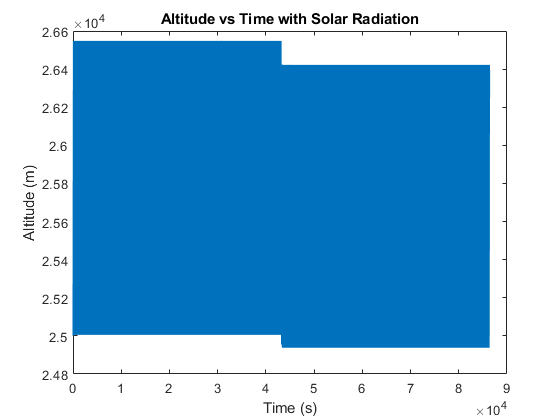

matChoice = 6;  %index of material choice in above calculations
r = r_balloon_25km(matChoice);  %radius
dt = 1;  %time step (s)
tTot = 86400;   %total sim length (s)
Ts = zeros(tTot/dt + 1, 1);  %initialize temperature matrix
Vs = zeros(tTot/dt + 1, 1);  %initialize velocity matrix
Hs = zeros(tTot/dt + 1, 1);  %initialize altitude matrix
As = zeros(tTot/dt + 1, 1);  %initialize acceleration matrix
Ts(1) = T(2);  %set first temperature to atmospheric temperature
Vs(1) = 0;  %set initial velocity to zero
Hs(1) = 25000;  %set first temperature to atmospheric temperature
As(1) = 0;  %set initial acceleration to zero
for ii = 1:(tTot/(2*dt))
    [Hs(ii+1),Vs(ii+1),As(ii+1),Ts(ii+1)] = updateHeight(Hs(ii),Vs(ii),As(ii),Ts(ii),r,m,t_shell_25km(matChoice),rho_shell(matChoice),m_gas_1_molecule,1,dt);  %recursively update height, speed, temp (daytime)
end
for ii = (tTot/(2*dt)):tTot/dt
    [Hs(ii+1),Vs(ii+1),As(ii+1),Ts(ii+1)] = updateHeight(Hs(ii),Vs(ii),As(ii),Ts(ii),r,m,t_shell_25km(matChoice),rho_shell(matChoice),m_gas_1_molecule,0,dt);  %recursively update height, speed, temp (nighttime)
end
ts = 0:dt:tTot;
figure()
plot(ts,Hs)
xlabel('Time (s)')
ylabel('Altitude (m)')
title('Altitude vs Time with Solar Radiation')

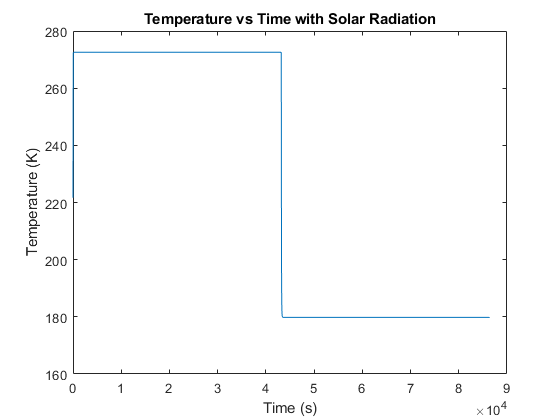

%figure()
%plot(ts,Vs)
%xlabel('Time (s)')
%ylabel('Velocity (m/s)')
%title('Velocity vs Time with Solar Radiation')
%figure()
%plot(ts,As)
%xlabel('Time (s)')
%ylabel('Acceleration (m/s^2)')
%title('Acceleration vs Time with Solar Radiation')
figure()
plot(ts,Ts)
xlabel('Time (s)')
ylabel('Temperature (K)')
title('Temperature vs Time with Solar Radiation')

Height Calculation Method 2

T_day = Ts(tTot/3)

T_day = 272.5641

T_night = Ts(tTot)

T_night = 179.7945

rho_air_start = rho_air(2);
height_start = 25000;
rho_He_start = rho_gas;

m_day = m %500 kg payload + 170 kg ballast

m_day = 600


m_gas_start = rho_He_start*((4/3)*pi*(r_balloon_25km(matChoice))^3)

m_gas_start = 115.0937


%High temperature - day
rho_He_day = (P_gage+P(2))/(R_c*T_day)

rho_He_day = 0.0045

V_day = (rho_He_start*((4/3)*pi*r_balloon_25km(matChoice)^3))/rho_He_day

V_day = 2.5846e+04

m_gas_day = rho_He_day*V_day

m_gas_day = 115.0937

r_day = ((3*V_day)/(4*pi))^(1/3)

r_day = 18.3416

rho_air_current = rho_air_start

rho_air_current = 0.0395

rho_air_day = (3*m_day)/(4*pi*r_day^3) + rho_He_start + (3*rho_shell(matChoice)*F_S(matChoice)*P_gage)/(2*Y_S(matChoice))

rho_air_day = 0.0341

height = height_start;

while(rho_air_day < rho_air_current)
    [~,~,~,rho_air_current] = atmoscoesa(height);
    height = height + 1;
end
heightHigh = height

heightHigh = 25918


%Low temperature - night
m_night = m - 100 %Drop 120 kg of ballast

m_night = 500


rho_He_night = (P_gage+P(2))/(R_c*T_night)

rho_He_night = 0.0068

V_night = (rho_He_start*((4/3)*pi*r_balloon_25km(matChoice)^3))/rho_He_night

V_night = 1.7049e+04

m_gas_night = rho_He_night*V_night

m_gas_night = 115.0937

r_night = ((3*V_night)/(4*pi))^(1/3)

r_night = 15.9664

rho_air_current = rho_air_start

rho_air_current = 0.0395

rho_air_night = (3*m_night)/(4*pi*r_night^3) + rho_He_start + (3*rho_shell(matChoice)*F_S(matChoice)*P_gage)/(2*Y_S(matChoice))

rho_air_night = 0.0402

height = height_start;

while(rho_air_night > rho_air_current)
    [~,~,~,rho_air_current] = atmoscoesa(height);
    height = height - 1;
end
heightLow = height

heightLow = 24875


m_shell = rho_shell(matChoice)*4*pi*r_day^2*t_shell_25km(matChoice)

m_shell = 131.4215


m_check = m_shell + m + m_gas_day  %Missing 35 kg

m_check = 846.5152


m_shell / m_check

ans = 0.1552

m_gas_day / m_check

ans = 0.1360

(m - ballast)/ m_check

ans = 0.5907

ballast / m_check

ans = 0.1181


W_check = m_check*g

W_check = 8.2958e+03

Fb_check = rho_air_day*g*V_day

Fb_check = 8.6468e+03

function [newT] = tempUpdate(oldT,r_balloon,daytime,rho_gas,dt)
    Eballoon = 0.8;
    BBconst = 5.670*10^-8;
    Absun = 0.6;
    Abearth = 0.8;
    qsun = 1353;
    qearth = 237;
    cP_He = 5190;
    Qballoon = Eballoon * BBconst * 4*pi*r_balloon^2 * oldT^4;
    Qsolar = Absun * qsun * pi * r_balloon^2 * daytime;
    Qearth = Abearth * qearth * pi * r_balloon^2;
    Qtot = Qsolar + Qearth - Qballoon;
    newT = oldT + Qtot/(4/3*pi*r_balloon^3*rho_gas * cP_He) * dt;
end

%function to update altitude based on temp, not currently working
function [newH,newV,newA,newT] = updateHeight(oldH,oldV,oldA,oldT,r_balloon,m_payload,t_shell,rho_shell,m_gas_mol,daytime,dt)
    g = 9.8;
    k = 1.38e-23;
    [~,~,P_old,~] = atmoscoesa(oldH);
    rho_gas_old = P_old * m_gas_mol / (k * oldT);
    newT = tempUpdate(oldT,r_balloon,daytime,rho_gas_old,dt);
    newH = oldH + oldV*dt + 1/2 * oldA * dt^2;
    [~,~,P_new,rho_air_new] = atmoscoesa(newH);
    rho_gas_new = P_new * m_gas_mol / (k * newT);
    m_tot = m_payload + rho_shell * (4*pi*r_balloon^2 * t_shell) + rho_gas_new * (4/3*pi*r_balloon^3);
    Fw = m_tot * g;
    Fb = g * 4/3 * pi * r_balloon^3 * rho_air_new;
    newA = (Fb - Fw)/m_tot;
    newV = oldV + (oldA + newA)/2 * dt;
end